clc;
close all;
clear all;

N = 1024;
fs = 2048;
ts = 1/fs;
%t = (0:ts:1);
t=(0:N-1)/fs;
fc = 600; %Carrier frequency
fm1 = 20;
Em1 = 1;


m = Em1*cos(2*pi*fm1*t); %Message
mh = Em1*cos((2*pi*fm1*t)-pi/2); %Hilbert transform of the message signal


sbu = m.*2.*cos(2*pi*fc*t) - mh.*2.*sin(2*pi*fc*t); %Expression for USB SSB
sbl = m.*2.*cos(2*pi*fc*t) + mh.*2.*sin(2*pi*fc*t); %Expression for LSB SSB

SBU = 2/N*abs(fft(sbu)); %Fourier Transform of USB SSB
SBL = 2/N*abs(fft(sbl)); %Fourier Transform of LSB SSB

SNR=10 % signal noise ratio

SNR = 10

ns=awgn(m,SNR,'measured') % adding white gaussian noise 

ns =     0.6270    1.1560    1.4226    0.9046    0.4831    0.7936    0.4726    0.8830    1.4173    0.6009    0.6843    1.1415    0.9103    0.8953    0.6990    0.6978    1.1548    0.3673    0.4004    0.2957    0.2776    0.0581    0.1071    0.6191   -0.1432    0.2214    0.2959   -0.1704   -0.2143   -0.3092   -0.1096   -0.6634   -0.2005   -0.4481   -0.6208   -0.7248   -0.3309   -0.5327   -0.5861   -1.0795   -0.5423   -0.8056   -0.9973   -0.4513   -0.5892   -0.5822   -1.0855   -1.1041   -1.1609   -0.8227


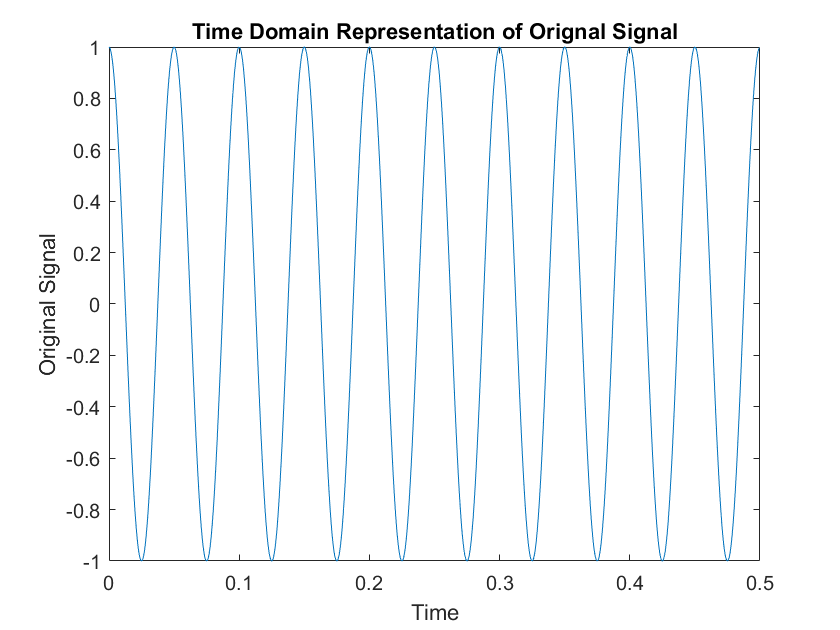



sbu_N = ns.*2.*cos(2*pi*fc*t) - mh.*2.*sin(2*pi*fc*t); %Expression for USB SSB
sbl_N = ns.*2.*cos(2*pi*fc*t) + mh.*2.*sin(2*pi*fc*t); %Expression for LSB SSB

SBU_N = 2/N*abs(fft(sbu_N)); %Fourier Transform of USB SSB
SBL_N = 2/N*abs(fft(sbl_N)); %Fourier Transform of LSB SSB

freq = fs * (0 : N/2) / N;

figure(1);
plot(t,m);
title('Time Domain Representation of Orignal Signal');
xlabel('Time'); ylabel('Original Signal');

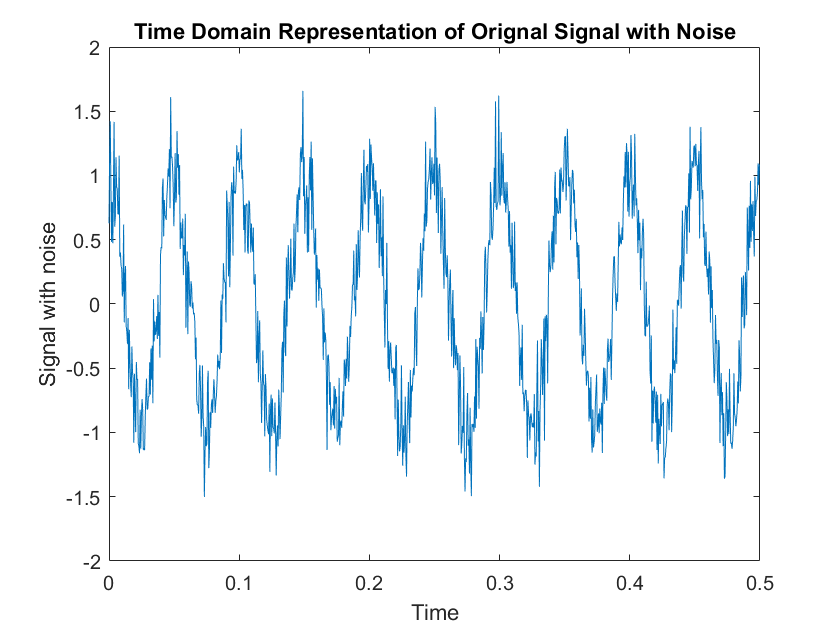


figure(2);
plot(t,ns) % signal with noise
title('Time Domain Representation of Orignal Signal with Noise');
xlabel('Time'); ylabel('Signal with noise');

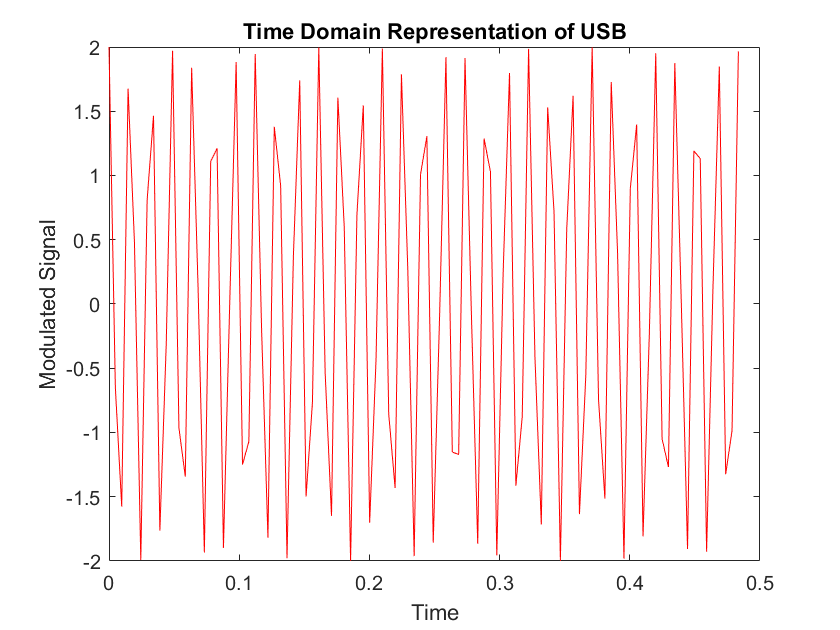


figure(3);
plot(10*t(1:100),sbu(1:100),'r');%Time Domain Plot of USB SSB
title('Time Domain Representation of USB');
xlabel('Time'); ylabel('Modulated Signal');

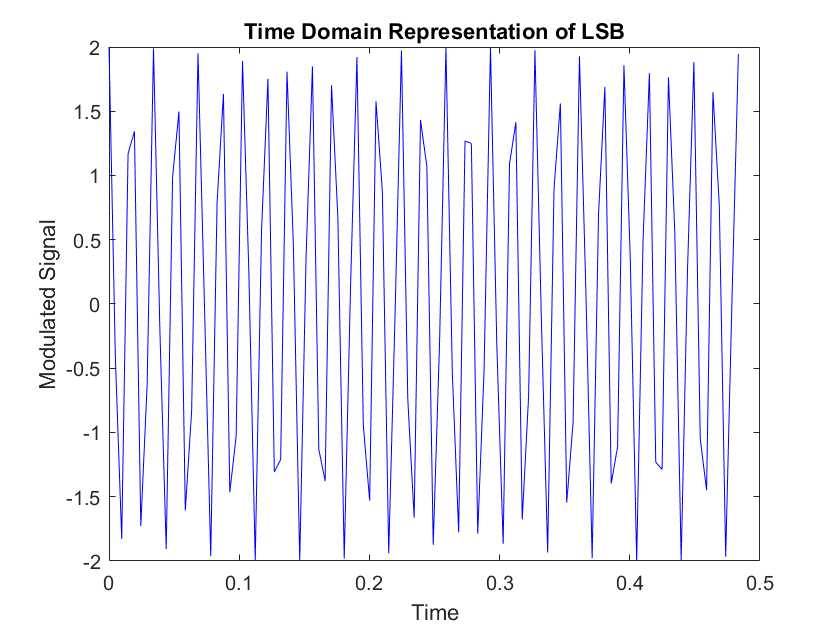


figure(4);
plot(10*t(1:100),sbl(1:100),'b');%Time Domain Plot of LSB SSB
title('Time Domain Representation of LSB');
xlabel('Time'); ylabel('Modulated Signal');

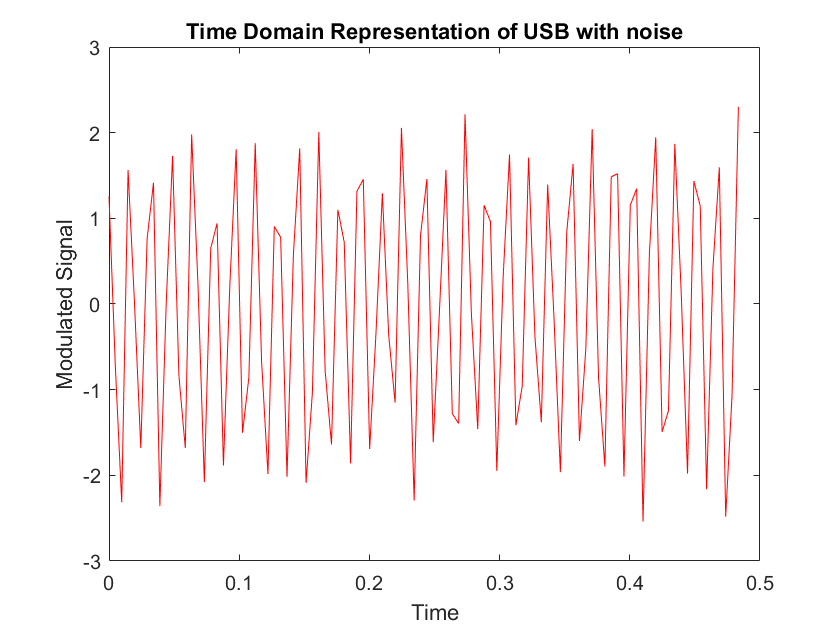


figure(5);
plot(10*t(1:100),sbu_N(1:100),'r');%Time Domain Plot of USB SSB
title('Time Domain Representation of USB with noise');
xlabel('Time'); ylabel('Modulated Signal');

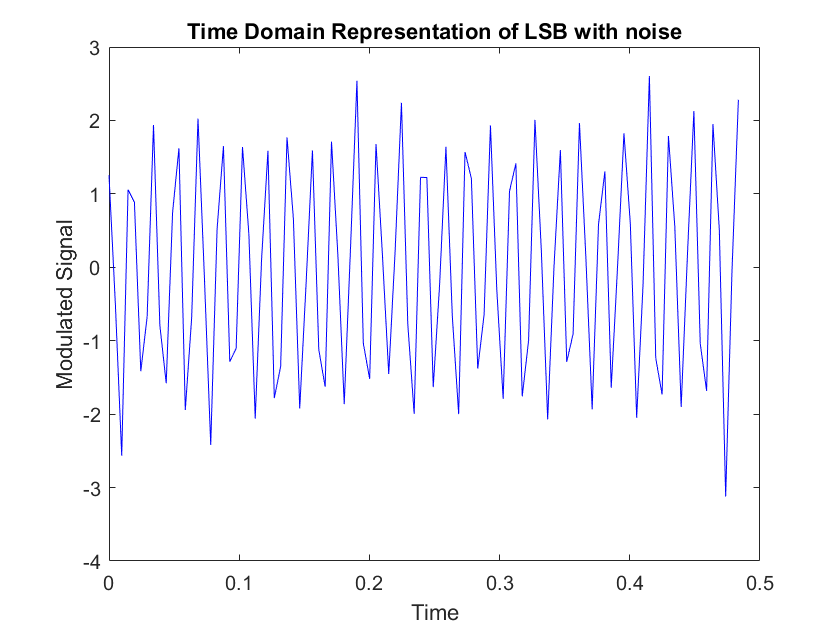


figure(6);
plot(10*t(1:100),sbl_N(1:100),'b');%Time Domain Plot of LSB SSB
title('Time Domain Representation of LSB with noise');
xlabel('Time'); ylabel('Modulated Signal');

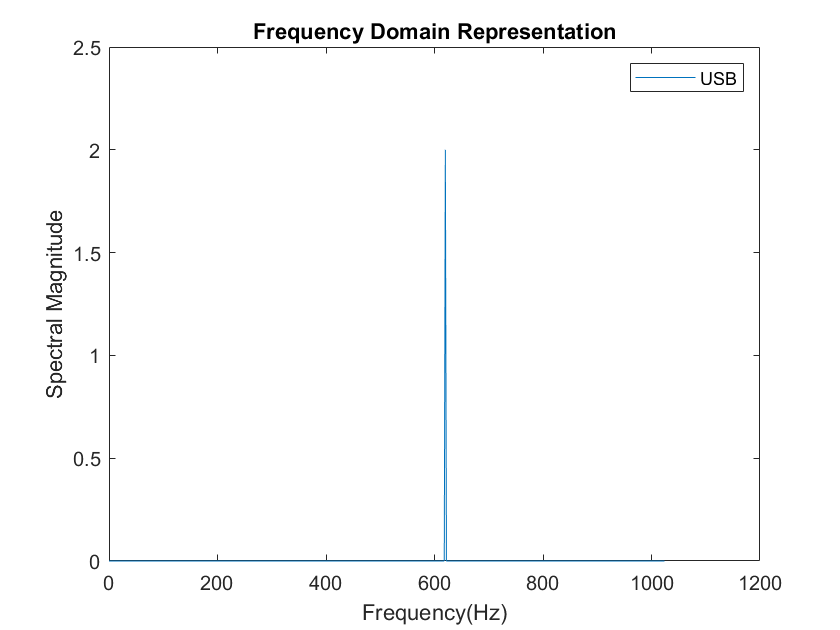


figure(7);
plot(freq,SBU(1:N/2+1))
title('Frequency Domain Representation');
xlabel('Frequency(Hz)'); ylabel('Spectral Magnitude');
legend('USB');

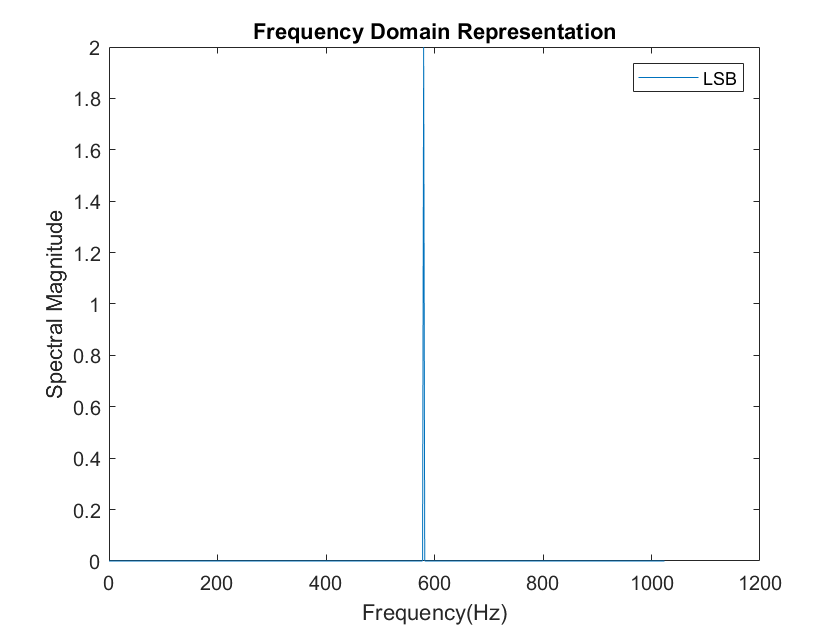


figure(8);
plot(freq,SBL(1:N/2+1)); %Frequency domain plot
title('Frequency Domain Representation');
xlabel('Frequency(Hz)'); ylabel('Spectral Magnitude');
legend('LSB');

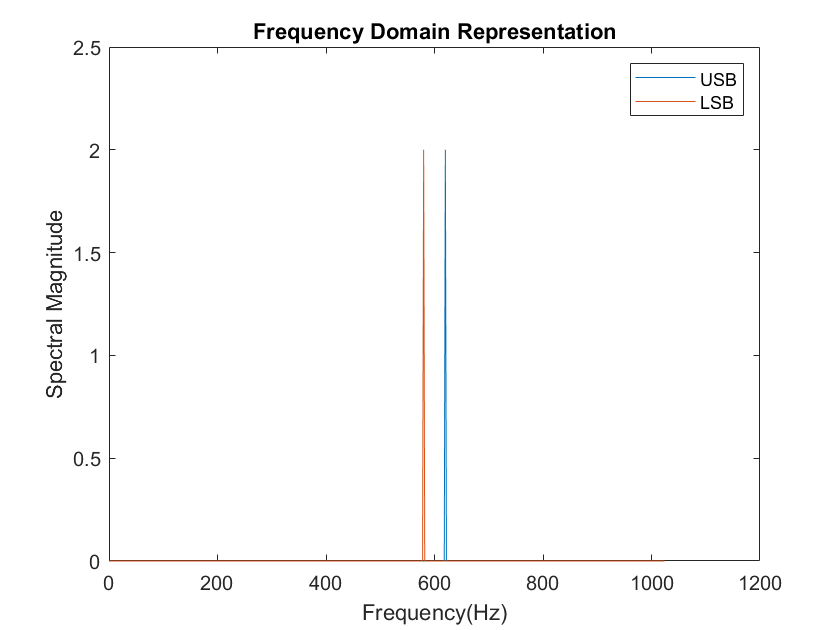


figure(9);
plot(freq,SBU(1:N/2+1),freq,SBL(1:N/2+1));
title('Frequency Domain Representation');
xlabel('Frequency(Hz)'); ylabel('Spectral Magnitude');
legend('USB','LSB');

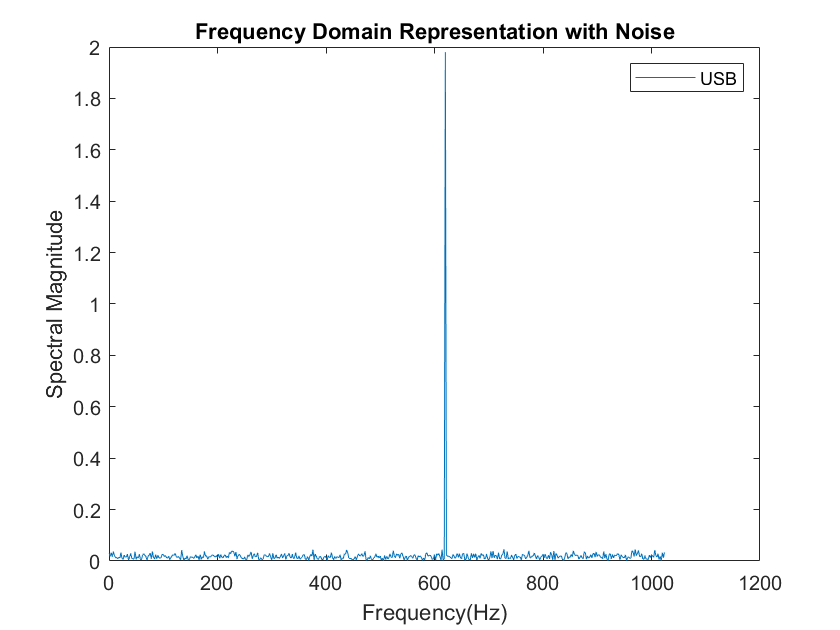


figure(10);
plot(freq,SBU_N(1:N/2+1))
title('Frequency Domain Representation with Noise');
xlabel('Frequency(Hz)'); ylabel('Spectral Magnitude');
legend('USB');

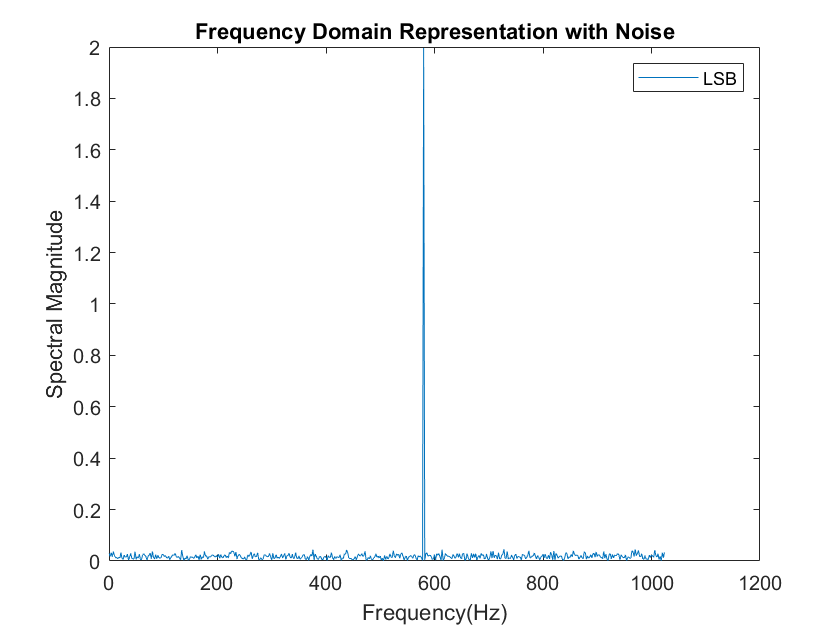


figure(11);
plot(freq,SBL_N(1:N/2+1)); %Frequency domain plot
title('Frequency Domain Representation with Noise');
xlabel('Frequency(Hz)'); ylabel('Spectral Magnitude');
legend('LSB');

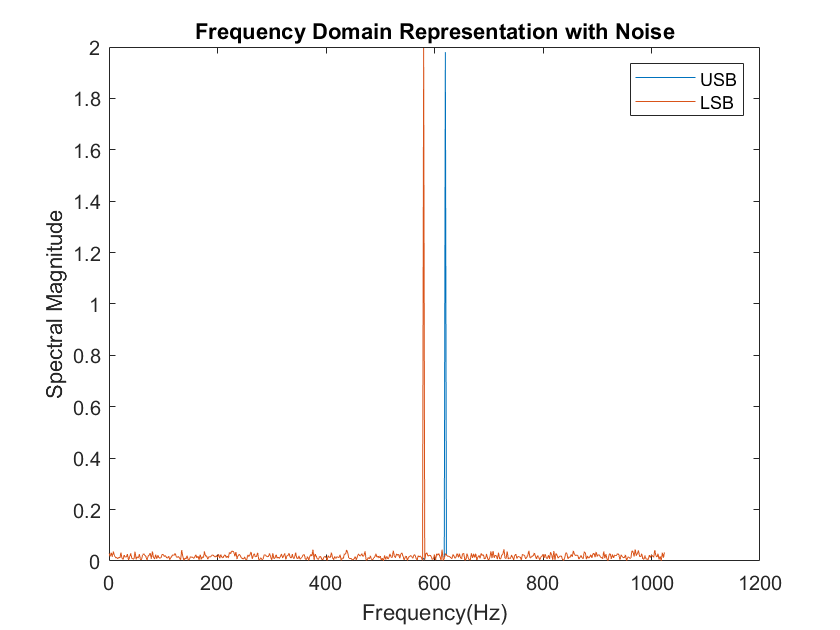


figure(12);
plot(freq,SBU_N(1:N/2+1),freq,SBL_N(1:N/2+1));
title('Frequency Domain Representation with Noise');
xlabel('Frequency(Hz)'); ylabel('Spectral Magnitude');
legend('USB','LSB');

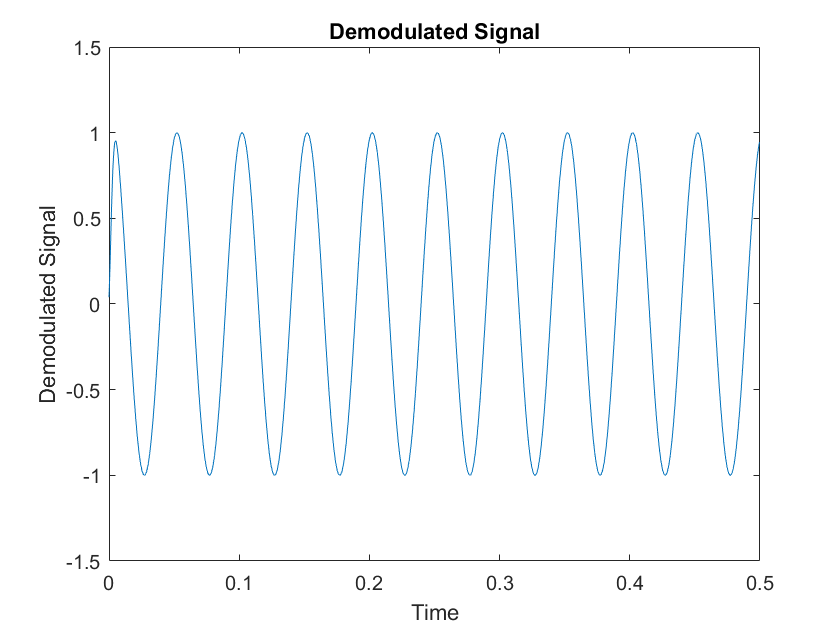



%Demodulation:
md=sbu.*cos(2*pi*fc*t);
[b,a]=butter(2,0.1);
mf=filter(b,a,md);
figure(13);
plot(t,mf)
title('Demodulated Signal');
xlabel('Time'); ylabel('Demodulated Signal');